Companion software for "Volker Ziemann, *Hands-on Accelerator physics using MATLAB, CRCPress, 2019*" (https://www.crcpress.com/9781138589940)

# Bunch muncher (Section 5.5)

Volker Ziemann, 211207, CC-BY-SA-4.0

**Important:** requires the elliptic package from [https://github.com/moiseevigor/elliptic](https://github.com/moiseevigor/elliptic) located in a subdirectory below the present one (for the fast evaluation of elliptic functions).

In [SLAC-PUB-5871](http://slac.stanford.edu/pubs/slacpubs/5750/slac-pub-5871.pdf) the authors describe a method, dubbed "bunch muncher," which is used to shorten the electron bunch in a damping ring of the SLC prior to injecting the bunch into the linear accelerator. It is based on temporarily reducing the RF-voltage, such that the bunch is lengthened, before resetting the RF-voltage to its initial value, such that the lengthened bunch rotates to an upright position in phase space, where it has a large momentum spread, but is shorter than the original bunch. 

## Matched initial distribution

In the first step we define the parameters of the system and prepare the initial particle distribution that is randomly distributed in a short range of phases and momenta. Then we move the coordinates of each particle forward in time by $1000$ synchrotron periods, which causes the initial distribution to smear out into a matched longitudinal distribution, which we use as starting distribution.

clear; 
addpath ./elliptic
Omegas=0.25; Ts=2*pi/Omegas; % synchrotron frequency
dt=1000*Ts;   % or 100*Ts   % <--- set time here
N=1000;      % number of particles
x0=[0.0,0.0]; dx=[0.5,0.1];  % center and spread of initialdistribution
x=zeros(N,2); x1=x;
for k=1:N   % loop over particles
  x(k,:)=x0+(rand(1,2)-0.5).*dx; 
  x1(k,:)=pendulumtracker(x(k,:),Omegas,dt); % initial distribution
end

We now save the initial distribution as` x` and also calculate the rms bunch length `initial_rms`, which is given in degree RF phase.

x=x1;
initial_rms=std(x1(:,1))*180/pi;

In the figure, we show the initial distribution as a cloud of green dots and the separatrix wit hthe full RF-voltage as a dashed black line.

figure
plot(x1(:,1),x1(:,2),'g.')
hold on
phi=-pi:0.01:pi; separatrix=2*Omegas*cos(0.5*phi);
plot(phi,separatrix,'k--',phi,-separatrix,'k--');

## Reducing the RF-voltage to a lower value

With two sliders we now set $\Omega_s$ to adjustthe RF-voltage and the duration `dt` of the munch, the duration that the voltage is lowered. Before calculating the phase-space positions after the selected duration, we plot the separatrix corresponding to the reduced RF-voltage as a black line.

Omegas=0.25*0.3;   % Slider for Omegas "Rf-voltage"
dt=Ts*0.8;      % Slider for duration of the munch
separatrix=2*Omegas*cos(0.5*phi);
plot(phi,separatrix,'k',phi,-separatrix,'k');
parfor k=1:N   % loop over particles, or use "for"
  x1(k,:)=pendulumtracker(x1(k,:),Omegas,dt);
end

After calculating the phase-space positions of the particles after the selected time, we plot them in the same diagram as a clound of red dots and annotate the axes. Note the rms bunch length before and after the selected duration displayed in the top-left corner of the plot. 

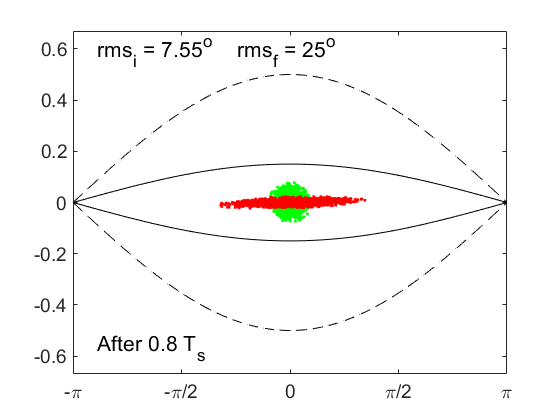

plot(x1(:,1),x1(:,2),'r.')
axis([-pi,pi,-0.67,0.67]);
set(gca,'xtick',[-pi,-pi/2,0,pi/2,pi],'fontsize',14, ...
     'xticklabels',{'-\pi','-\pi/2','0','\pi/2','\pi'})
text(-2.8,-0.57,['After ',num2str(dt/Ts,3),' T_s'],'fontsize',16) 
final_rms=std(x1(:,1))*180/pi;
text(-2.8,0.59,['rms_i = ',num2str(initial_rms,3),'^o    rms_f = ',num2str(final_rms,3),'^o'], ...
  'FontSize',16)

At this point the bunch distribution is sheared and much longer, but at the same time the momentum spread is reduced somewhat.

## Turning the RF-voltage back to the original value

Now we reset the RF-voltage, or $\Omega_s$ to its initial value and wait for about a quarter of a synchrotron period, which rotates the sheared distribution to an upright position, such that the bunch is short, but has a large momentum spread. The slider allows us to fine-tune the time  extract the beam until it is fully upright.

Omegas=0.25;
dt=Ts*0.26; % Slider to set extraction time
figure
phi=-pi:0.01:pi; separatrix=2*Omegas*cos(0.5*phi);
plot(phi,separatrix,'k',phi,-separatrix,'k');
hold on
parfor k=1:N   % loop over particles, or use "for"
  x1(k,:)=pendulumtracker(x1(k,:),Omegas,dt);
end

Again, we plot the final distribution as a cloud of red dots, annotate teh axes, and display the final rms bunch length in the top-left corner of the plot.

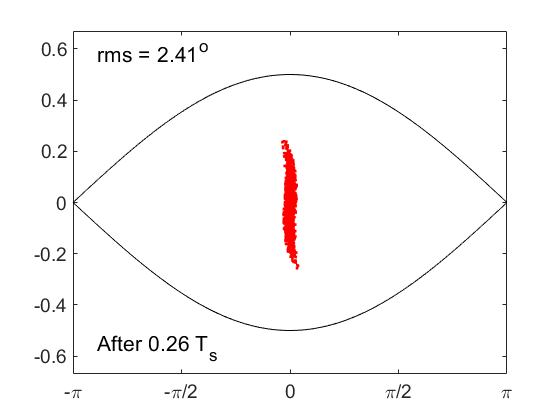

plot(x1(:,1),x1(:,2),'r.')
axis([-pi,pi,-0.67,0.67]);
set(gca,'xtick',[-pi,-pi/2,0,pi/2,pi],'fontsize',14, ...
     'xticklabels',{'-\pi','-\pi/2','0','\pi/2','\pi'})
text(-2.8,-0.57,['After ',num2str(dt/Ts,3),' T_s'],'fontsize',16) 
rot_rms=std(x1(:,1))*180/pi;
text(-2.8,0.59,['rms = ',num2str(rot_rms,3),'^o'],'FontSize',16)

Finnaly we display the longitudinal distributions of the initial and final stage in histograms. The upper part of the following plot shows the projection of the initial distribution, corresponding to the cloud of green dots shown on a earlier plot, and display its rms width in the legend. Then we repeat the same thing with the final distribution after the bunch rotation and display the ratio of the rms values as the `compression`.

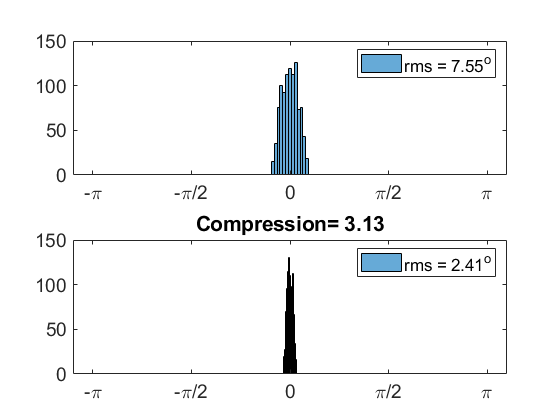

figure
compression=initial_rms/rot_rms;
subplot(2,1,1); histogram(x(:,1),'BinLimits',[-pi,pi])
legend(['rms = ',num2str(initial_rms,3),'^o'])
set(gca,'xtick',[-pi,-pi/2,0,pi/2,pi],'fontsize',14, ...
   'xticklabels',{'-\pi','-\pi/2','0','\pi/2','\pi'})
subplot(2,1,2); histogram(x1(:,1),'BinLimits',[-pi,pi])
legend(['rms = ',num2str(rot_rms,3),'^o'])
set(gca,'xtick',[-pi,-pi/2,0,pi/2,pi],'fontsize',14, ...
   'xticklabels',{'-\pi','-\pi/2','0','\pi/2','\pi'})
title(['Compression= ',num2str(compression,3)])

Now feel feel to play with the sliders and increase the compression factor. 

## Appendix 

The function` pendulumtracker()` receives the phase-space coordinates `x` at the start, the small-amplitude synchrotron frequency `omega`, and the integration time `dt` as input and returns the phase-space coordinates `xout`. Internally, it integrates the equations of motion for a mathematical pendulum in closed form using Jacobi elliptic functions. This is much faster than numerically integration, expecially for extremely large times, such as thousands or even millions of synchrotron periods. The coding closely follows Section 5.4, especially Equations 5.50 to 5.54. Here we use the elliptic functions from [https://github.com/moiseevigor/elliptic](https://github.com/moiseevigor/elliptic).

function xout=pendulumtracker(x,omega,dt)
k2=(0.5*x(2)/omega)^2+sin(0.5*x(1))^2; k=sqrt(k2);
if (x(1)>pi), x(1)=x(1)-2*pi; end
if (x(1)<-pi), x(1)=x(1)+2*pi; end
s=1; if (x(1)<0), s=-s; x(1)=-x(1); end
s1=1; if (x(2)<0), s1=-s1; end
if (k>1)   % outside separatrix
  kelf=ellipke(1/k2);
  trev=2*kelf/(k*omega);
  t0=mod(dt,trev);
  tmp=s1*k*omega*t0+s*elliptic12(0.5*x(1),1/k2);
  [sn,cn,dn]=ellipj(tmp,1/k2);  
  if (abs(tmp) > kelf), sn=-sn; end
  xout(1)=2*asin(sn);
  xout(2)=2*s1*omega*k*dn;
else       % inside separatrix
  trev=4*ellipke(k2)/omega;
  t0=mod(dt,trev);
  z0=asin(min(1,sin(0.5*x(1))/k));
  tmp=s1*omega*t0+s*elliptic12(z0,k2);
  [sn,cn,dn]=ellipj(tmp,k2);   
  xout(1)=2*asin(k*sn);
  xout(2)=2*s1*omega*k*cn;
end
end
